# **5) Mapa de ocupación**

% % =========================================================================
% % EKF-SLAM y Occupancy Grid Mapping (Log-Odds) para Robot MiR100
% % =========================================================================
% clear; clc; close all;
% 
% %% 1. Cargar el archivo ROSBAG
% filePath = 'mir_basics_20251210_114529.bag'; % Reemplaza con tu archivo
% disp('Abriendo archivo rosbag...');

Abriendo archivo rosbag...


% bag = rosbag(filePath);
% 
% bagOdom = select(bag, 'Topic', '/odom');
% bagScan = select(bag, 'Topic', '/scan');
% bagGT   = select(bag, 'Topic', '/base_pose_ground_truth');
% 
% time_odom = bagOdom.MessageList.Time;
% time_scan = bagScan.MessageList.Time;
% time_gt   = bagGT.MessageList.Time;
% 
% disp('Leyendo mensajes del rosbag...');

Leyendo mensajes del rosbag...


% odomMsgs = readMessages(bagOdom, 'DataFormat', 'struct');
% scanMsgs = readMessages(bagScan, 'DataFormat', 'struct');
% gtMsgs   = readMessages(bagGT, 'DataFormat', 'struct');
% 
% %% 1.1 Extraer y Alinear Ground Truth
% total_scan_msgs = length(scanMsgs);
% 
% [~, first_gt_idx] = min(abs(time_gt - time_scan(1)));
% start_gt_pos = [gtMsgs{first_gt_idx}.Pose.Pose.Position.X, gtMsgs{first_gt_idx}.Pose.Pose.Position.Y];
% quat_gt = gtMsgs{first_gt_idx}.Pose.Pose.Orientation;
% start_gt_yaw = quat2yaw([quat_gt.W, quat_gt.X, quat_gt.Y, quat_gt.Z]);
% 
% gt_x = cellfun(@(m) m.Pose.Pose.Position.X - start_gt_pos(1), gtMsgs);
% gt_y = cellfun(@(m) m.Pose.Pose.Position.Y - start_gt_pos(2), gtMsgs);
% 
% %% 2. Inicialización de Variables EKF y OCCUPANCY GRID (NUEVO)
% mu = [0; 0; start_gt_yaw]; 
% Sigma = diag([0.1, 0.1, deg2rad(5)].^2); 
% R = diag([0.05, 0.05, 0.02].^2); 
% Q = diag([0.1, deg2rad(1)].^2);  
% trajectory = zeros(total_scan_msgs, 3);
% map_landmarks = []; 
% 
% [~, first_odom_idx] = min(abs(time_odom - time_scan(1)));
% last_odom_pos = [odomMsgs{first_odom_idx}.Pose.Pose.Position.X, odomMsgs{first_odom_idx}.Pose.Pose.Position.Y];
% quat_odom = odomMsgs{first_odom_idx}.Pose.Pose.Orientation;
% last_odom_yaw = quat2yaw([quat_odom.W, quat_odom.X, quat_odom.Y, quat_odom.Z]);
% 
% % --- PARÁMETROS DEL MAPA DE OCUPACIÓN (LOG-ODDS) ---
% map_size = 500;             % Tamaño de la rejilla (500x500 píxeles)
% map_res = 0.08;             % Resolución: 0.08 metros/pixel (Entorno de 40x40m)
% map_log_odds = zeros(map_size, map_size); % Inicia en 0 (Probabilidad 0.5 - Desconocido)
% l_occ = log(0.7 / 0.3);     % Evidencia a sumar si la celda está ocupada (~0.84)
% l_free = log(0.3 / 0.7);    % Evidencia a restar si la celda está libre (~-0.84)
% 
% %% 3. Bucle Principal
% disp('Iniciando EKF-SLAM y Construcción del Mapa de Ocupación...');

Iniciando EKF-SLAM y Construcción del Mapa de Ocupación...


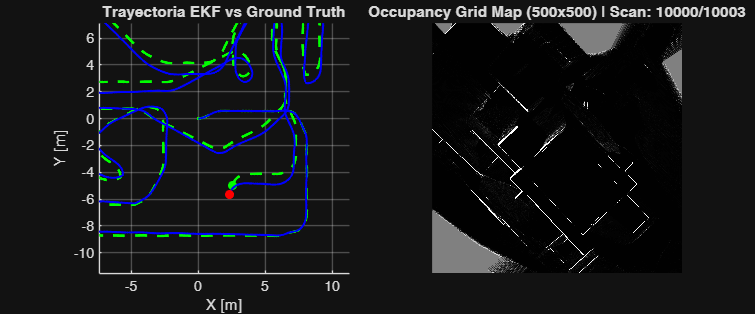

% figure('Name', 'EKF-SLAM & Occupancy Grid', 'NumberTitle', 'off', 'Position', [100, 100, 1200, 500]);
% 
% for i = 1:total_scan_msgs
%     current_time = time_scan(i);
% 
%     % --- A. PREDICCIÓN (Odometría Sincronizada) ---
%     [~, idx_odom] = min(abs(time_odom - current_time));
%     curr_odom = odomMsgs{idx_odom}; 
% 
%     curr_pos = [curr_odom.Pose.Pose.Position.X, curr_odom.Pose.Pose.Position.Y];
%     quat_curr = curr_odom.Pose.Pose.Orientation;
%     curr_yaw = quat2yaw([quat_curr.W, quat_curr.X, quat_curr.Y, quat_curr.Z]);
% 
%     delta_trans = norm(curr_pos - last_odom_pos);
%     delta_rot = angdiff(last_odom_yaw, curr_yaw);
% 
%     theta = mu(3);
%     mu(1) = mu(1) + delta_trans * cos(theta + delta_rot/2);
%     mu(2) = mu(2) + delta_trans * sin(theta + delta_rot/2);
%     mu(3) = wrapToPi(mu(3) + delta_rot);
% 
%     N = length(mu);
%     Fx = [eye(3), zeros(3, N-3)]; 
%     G_t = eye(N) + Fx' * [0, 0, -delta_trans * sin(theta + delta_rot/2);
%                           0, 0,  delta_trans * cos(theta + delta_rot/2);
%                           0, 0,  0] * Fx;
% 
%     Sigma = G_t * Sigma * G_t' + Fx' * R * Fx;
%     last_odom_pos = curr_pos;
%     last_odom_yaw = curr_yaw;
% 
%     % --- B. EXTRACCIÓN DE CARACTERÍSTICAS (EKF) ---
%     scan = scanMsgs{i};
%     [z_ranges, z_angles] = extractLandmarksFromScan(scan);
% 
%     % --- C. ACTUALIZACIÓN EKF ---
%     for j = 1:length(z_ranges)
%         r_meas = z_ranges(j); phi_meas = z_angles(j);
%         m_x_est = mu(1) + r_meas * cos(mu(3) + phi_meas);
%         m_y_est = mu(2) + r_meas * sin(mu(3) + phi_meas);
% 
%         best_idx = 0; min_dist_sq = 1e6; distance_threshold = 0.5; 
%         if length(mu) > 3
%             landmarks = [mu(4:2:end), mu(5:2:end)];
%             for k = 1:size(landmarks, 1)
%                 dist_sq = (landmarks(k, 1) - m_x_est)^2 + (landmarks(k, 2) - m_y_est)^2;
%                 if dist_sq < min_dist_sq
%                     min_dist_sq = dist_sq; best_idx = k;
%                 end
%             end
%         end
% 
%         if best_idx > 0 && min_dist_sq < distance_threshold^2
%             idx = best_idx;
%         else
%             map_landmarks = [map_landmarks; length(map_landmarks) + 1]; 
%             mu = [mu; m_x_est; m_y_est];
%             Sigma = blkdiag(Sigma, eye(2)*100); 
%             idx = length(map_landmarks);
%         end
% 
%         lm_idx_x = 3 + 2*(idx-1) + 1; lm_idx_y = 3 + 2*idx;
%         delta_x = mu(lm_idx_x) - mu(1); delta_y = mu(lm_idx_y) - mu(2);
%         q = delta_x^2 + delta_y^2;
%         z_hat = [sqrt(q); wrapToPi(atan2(delta_y, delta_x) - mu(3))];
% 
%         N = length(mu); Fx_j = zeros(5, N);
%         Fx_j(1:3, 1:3) = eye(3); Fx_j(4:5, lm_idx_x:lm_idx_y) = eye(2);
% 
%         h_matrix = [-delta_x/sqrt(q), -delta_y/sqrt(q), 0, delta_x/sqrt(q), delta_y/sqrt(q);
%                      delta_y/q,       -delta_x/q,      -1, -delta_y/q,       delta_x/q];
%         H_t = h_matrix * Fx_j;
%         S = H_t * Sigma * H_t' + Q;
%         K = Sigma * H_t' / S;
%         innov = [r_meas - z_hat(1); wrapToPi(phi_meas - z_hat(2))];
%         mu = mu + K * innov;
%         Sigma = (eye(N) - K * H_t) * Sigma;
%     end
%     trajectory(i, :) = mu(1:3)';
% 
%     % --- D. CONSTRUCCIÓN MAPA DE OCUPACIÓN (NUEVO) ---
%     % Llamar a la función que actualiza la matriz Log-Odds usando la pose EKF actual
%     map_log_odds = updateOccupancyGrid(map_log_odds, mu(1:3), scan, map_size, map_res, l_occ, l_free);
% 
%     % --- E. VISUALIZACIÓN EN TIEMPO REAL ---
%     if mod(i, 20) == 0 
%         % 1. Subplot Izquierdo: EKF-SLAM y Ground Truth
%         subplot(1, 2, 1); cla; hold on; grid on; axis equal;
%         title('Trayectoria EKF vs Ground Truth'); xlabel('X [m]'); ylabel('Y [m]');
%         axis([-15 15 -15 15]); 
% 
%         [~, idx_gt] = min(abs(time_gt - current_time));
%         if idx_gt > first_gt_idx
%             plot(gt_x(first_gt_idx:idx_gt), gt_y(first_gt_idx:idx_gt), 'g--', 'LineWidth', 2);
%             plot(gt_x(idx_gt), gt_y(idx_gt), 'go', 'MarkerFaceColor', 'g');
%         end
%         plot(trajectory(1:i, 1), trajectory(1:i, 2), 'b-', 'LineWidth', 1.5);
%         plot(mu(1), mu(2), 'ro', 'MarkerFaceColor', 'r');
%         if length(mu) > 3
%             plot(mu(4:2:end), mu(5:2:end), 'k*', 'MarkerSize', 5);
%         end
% 
%         % 2. Subplot Derecho: Occupancy Grid Map 500x500
%         subplot(1, 2, 2); 
%         % Convertir log-odds a probabilidad para visualización en escala de grises
%         % Ocupado = negro (0), Libre = blanco (1), Desconocido = gris (0.5)
%         prob_map = 1 - (1 ./ (1 + exp(map_log_odds)));
% 
%         % Transponer y voltear para que los ejes XY coincidan con la vista de cámara/mundo
%         imshow(flipud(prob_map'), 'InitialMagnification', 'fit');
%         title(['Occupancy Grid Map (500x500) | Scan: ', num2str(i), '/', num2str(total_scan_msgs)]);
%         colormap(gray);
% 
%         drawnow;
%     end
% end

% disp('Simulación Finalizada.');

Simulación Finalizada.


% 
% %% ========================================================================
% % FUNCIONES DE MAPEO (NUEVAS)
% % =========================================================================
% 
% function map = updateOccupancyGrid(map, pose, scanMsg, map_size, map_res, l_occ, l_free)
%     % Convierte los datos del sensor y el robot en celdas de cuadrícula usando Log-Odds
% 
%     ranges = double(scanMsg.Ranges);
%     angle_min = double(scanMsg.AngleMin);
%     angle_inc = double(scanMsg.AngleIncrement);
%     angles = angle_min + (0:length(ranges)-1)' * angle_inc;
%     max_range = double(scanMsg.RangeMax);
%     if isnan(max_range) || max_range > 30, max_range = 10; end % Límite de seguridad
% 
%     % Posición del robot en el mapa (El origen 0,0 mundo es el centro del mapa 250,250)
%     rx = pose(1); ry = pose(2); theta = pose(3);
%     cx_r = round(rx / map_res) + map_size / 2;
%     cy_r = round(ry / map_res) + map_size / 2;
% 
%     for k = 1:length(ranges)
%         r = ranges(k);
%         if isnan(r) || r < double(scanMsg.RangeMin)
%             continue; 
%         end
% 
%         is_occupied = true;
%         if isinf(r) || r >= max_range
%             r = max_range; 
%             is_occupied = false; % El láser no golpeó nada, trazamos espacio libre
%         end
% 
%         % Fin del rayo láser en el mundo real
%         px = rx + r * cos(theta + angles(k));
%         py = ry + r * sin(theta + angles(k));
% 
%         % Conversión a índices de celda
%         cx_p = round(px / map_res) + map_size / 2;
%         cy_p = round(py / map_res) + map_size / 2;
% 
%         % Trazado de rayos con Bresenham
%         [cells_x, cells_y] = bresenham(cx_r, cy_r, cx_p, cy_p);
% 
%         % Actualizar evidencia (Libre a lo largo del rayo)
%         for c = 1:length(cells_x)-1
%             x_idx = cells_x(c); y_idx = cells_y(c);
%             if x_idx >= 1 && x_idx <= map_size && y_idx >= 1 && y_idx <= map_size
%                 % Saturación para evitar sobreconfianza absoluta
%                 map(x_idx, y_idx) = max(map(x_idx, y_idx) + l_free, -5);
%             end
%         end
% 
%         % Actualizar evidencia (Ocupado al final del rayo)
%         if is_occupied && ~isempty(cells_x)
%             x_idx = cells_x(end); y_idx = cells_y(end);
%             if x_idx >= 1 && x_idx <= map_size && y_idx >= 1 && y_idx <= map_size
%                 map(x_idx, y_idx) = min(map(x_idx, y_idx) + l_occ, 5);
%             end
%         end
%     end
% end
% 
% function [x, y] = bresenham(x1, y1, x2, y2)
%     % Algoritmo de trazado de líneas de Bresenham para celdas discretas
%     dx = abs(x2 - x1); dy = abs(y2 - y1);
%     sx = sign(x2 - x1); sy = sign(y2 - y1);
%     err = dx - dy;
% 
%     x = []; y = [];
%     while true
%         x = [x; x1]; y = [y; y1];
%         if x1 == x2 && y1 == y2, break; end
%         e2 = 2 * err;
%         if e2 > -dy, err = err - dy; x1 = x1 + sx; end
%         if e2 < dx, err = err + dx; y1 = y1 + sy; end
%     end
% end
% 
% %% ========================================================================
% % FUNCIONES AUXILIARES EKF (MANTENIDAS DE ANTES)
% % =========================================================================
% 
% function yaw = quat2yaw(q)
%     yaw = atan2(2*(q(1)*q(4) + q(2)*q(3)), 1 - 2*(q(3)^2 + q(4)^2));
% end
% 
% function diff = angdiff(th1, th2)
%     diff = wrapToPi(th2 - th1);
% end
% 
% function [r, phi] = extractLandmarksFromScan(scanMsg)
%     threshold = 0.15; 
%     ranges = double(scanMsg.Ranges);
%     angle_min = double(scanMsg.AngleMin);
%     angle_increment = double(scanMsg.AngleIncrement);
%     angles = angle_min + (0:length(ranges)-1) * angle_increment;
%     valid_indices = isfinite(ranges); 
%     x_local = ranges(valid_indices) .* cos(angles(valid_indices));
%     y_local = ranges(valid_indices) .* sin(angles(valid_indices));
%     points = [x_local', y_local'];
%     if size(points, 1) < 5
%         r = []; phi = []; return;
%     end
%     corners = split_and_merge(points, threshold);
%     if isempty(corners)
%         r = []; phi = [];
%     else
%         r = sqrt(corners(:,1).^2 + corners(:,2).^2);
%         phi = atan2(corners(:,2), corners(:,1));
%     end
% end
% 
% function corners = split_and_merge(points, threshold)
%     if size(points, 1) < 2
%         corners = []; return;
%     end
%     p1 = points(1, :); p2 = points(end, :); max_dist = 0; idx_split = 0;
%     for k = 2:(size(points, 1) - 1)
%         pk = points(k, :);
%         cross_product = abs((p2(1) - p1(1))*(pk(2) - p1(2)) - (p2(2) - p1(2))*(pk(1) - p1(1)));
%         line_length = sqrt((p2(1) - p1(1))^2 + (p2(2) - p1(2))^2);
%         if line_length == 0
%             dist = sqrt((pk(1) - p1(1))^2 + (pk(2) - p1(2))^2);
%         else
%             dist = cross_product / line_length;
%         end
%         if dist > max_dist
%             max_dist = dist; idx_split = k;
%         end
%     end
%     if max_dist > threshold
%         corners_left = split_and_merge(points(1:idx_split, :), threshold);
%         corners_right = split_and_merge(points(idx_split:end, :), threshold);
%         corners = [corners_left; points(idx_split, :); corners_right];
%         corners = unique(corners, 'rows', 'stable'); 
%     else
%         corners = []; 
%     end
% end

# **4) EKF SLAM Y GROUND TRUTH SINCRONIZADOS**

 Se corrigió la desincronización temporal de los tópicos. En ROS, los sensores no publican datos exactamente al mismo tiempo ni a la misma frecuencia.

En el código 3, estábamos asumiendo que los mensajes se podían emparejar de forma "proporcional" . Si el tópico `/scan` empezó a grabar dos segundos después que el Ground Truth, o si se detuvo antes, una relación proporcional causará esos desfases y recortes visuales que estás viendo.

**SOLUCIÓN: **MATLAB que lea el tiempo exacto en el que se grabó cada mensaje de láser, y luego busque exactamente la odometría y el Ground Truth que coincidan con ese milisegundo.

% =========================================================================
% EKF-SLAM para Robot MiR100 - VERSIÓN SINCRONIZADA POR TIEMPO
% =========================================================================
clear; clc; close all;

%% 1. Cargar el archivo ROSBAG
filePath = 'mir_basics_20251210_114529.bag'; % Reemplaza con tu archivo
disp('Abriendo archivo rosbag...');
bag = rosbag(filePath);

% Seleccionar los tópicos relevantes
bagOdom = select(bag, 'Topic', '/odom');
bagScan = select(bag, 'Topic', '/scan');
bagGT   = select(bag, 'Topic', '/base_pose_ground_truth');

% NUEVO: Extraer las marcas de tiempo (Timestamps) de cada tópico
time_odom = bagOdom.MessageList.Time;
time_scan = bagScan.MessageList.Time;
time_gt   = bagGT.MessageList.Time;

% Leer los mensajes
disp('Leyendo mensajes del rosbag...');
odomMsgs = readMessages(bagOdom, 'DataFormat', 'struct');
scanMsgs = readMessages(bagScan, 'DataFormat', 'struct');
gtMsgs   = readMessages(bagGT, 'DataFormat', 'struct');

%% 1.1 Extraer y Alinear Ground Truth (SINCRONIZADO)
total_scan_msgs = length(scanMsgs);

% NUEVO: Buscar el GT que coincida exactamente con el PRIMER SCAN
[~, first_gt_idx] = min(abs(time_gt - time_scan(1)));

start_gt_pos = [gtMsgs{first_gt_idx}.Pose.Pose.Position.X, gtMsgs{first_gt_idx}.Pose.Pose.Position.Y];
quat_gt = gtMsgs{first_gt_idx}.Pose.Pose.Orientation;
start_gt_yaw = quat2yaw([quat_gt.W, quat_gt.X, quat_gt.Y, quat_gt.Z]);

% Extraemos poses de GT de forma vectorizada y RELATIVA al inicio sincronizado
gt_x = cellfun(@(m) m.Pose.Pose.Position.X - start_gt_pos(1), gtMsgs);
gt_y = cellfun(@(m) m.Pose.Pose.Position.Y - start_gt_pos(2), gtMsgs);

%% 2. Inicialización de Variables y Matrices EKF
mu = [0; 0; start_gt_yaw]; 
Sigma = diag([0.1, 0.1, deg2rad(5)].^2); 

R = diag([0.05, 0.05, 0.02].^2); 
Q = diag([0.1, deg2rad(1)].^2);  

trajectory = zeros(total_scan_msgs, 3);
map_landmarks = []; 

% NUEVO: Sincronizar la primera odometría con el primer scan
[~, first_odom_idx] = min(abs(time_odom - time_scan(1)));
last_odom_pos = [odomMsgs{first_odom_idx}.Pose.Pose.Position.X, odomMsgs{first_odom_idx}.Pose.Pose.Position.Y];
quat_odom = odomMsgs{first_odom_idx}.Pose.Pose.Orientation;
last_odom_yaw = quat2yaw([quat_odom.W, quat_odom.X, quat_odom.Y, quat_odom.Z]);

%% 3. Bucle Principal de EKF-SLAM
disp('Iniciando EKF-SLAM con Sincronización Temporal...');
figure('Name', 'EKF-SLAM Sincronizado', 'NumberTitle', 'off');
hold on; grid on; axis equal;
xlabel('X [m]'); ylabel('Y [m]'); 
title('Estimación EKF-SLAM vs Ground Truth (Sincronizado)');
axis([-15 15 -15 15]); 

for i = 1:total_scan_msgs

    current_time = time_scan(i); % Tiempo actual basado en el LiDAR

    % --- A. PREDICCIÓN (Odometría Sincronizada) ---
    % NUEVO: Buscar la odometría exacta para este instante de tiempo
    [~, idx_odom] = min(abs(time_odom - current_time));
    curr_odom = odomMsgs{idx_odom}; 

    curr_pos = [curr_odom.Pose.Pose.Position.X, curr_odom.Pose.Pose.Position.Y];
    quat_curr = curr_odom.Pose.Pose.Orientation;
    curr_yaw = quat2yaw([quat_curr.W, quat_curr.X, quat_curr.Y, quat_curr.Z]);

    delta_trans = norm(curr_pos - last_odom_pos);
    delta_rot = angdiff(last_odom_yaw, curr_yaw);

    theta = mu(3);
    mu(1) = mu(1) + delta_trans * cos(theta + delta_rot/2);
    mu(2) = mu(2) + delta_trans * sin(theta + delta_rot/2);
    mu(3) = wrapToPi(mu(3) + delta_rot);

    N = length(mu);
    Fx = [eye(3), zeros(3, N-3)]; 

    G_t = eye(N) + Fx' * [0, 0, -delta_trans * sin(theta + delta_rot/2);
                          0, 0,  delta_trans * cos(theta + delta_rot/2);
                          0, 0,  0] * Fx;

    Sigma = G_t * Sigma * G_t' + Fx' * R * Fx;

    last_odom_pos = curr_pos;
    last_odom_yaw = curr_yaw;

    % --- B. EXTRACCIÓN DE CARACTERÍSTICAS ---
    scan = scanMsgs{i};
    [z_ranges, z_angles] = extractLandmarksFromScan(scan);

    % --- C. ACTUALIZACIÓN ---
    for j = 1:length(z_ranges)
        r_meas = z_ranges(j);
        phi_meas = z_angles(j);

        m_x_est = mu(1) + r_meas * cos(mu(3) + phi_meas);
        m_y_est = mu(2) + r_meas * sin(mu(3) + phi_meas);

        best_idx = 0;
        min_dist_sq = 1e6;
        distance_threshold = 0.5; 

        if length(mu) > 3
            landmarks = [mu(4:2:end), mu(5:2:end)];
            for k = 1:size(landmarks, 1)
                dist_sq = (landmarks(k, 1) - m_x_est)^2 + (landmarks(k, 2) - m_y_est)^2;
                if dist_sq < min_dist_sq
                    min_dist_sq = dist_sq;
                    best_idx = k;
                end
            end
        end

        if best_idx > 0 && min_dist_sq < distance_threshold^2
            idx = best_idx;
        else
            map_landmarks = [map_landmarks; length(map_landmarks) + 1]; 
            mu = [mu; m_x_est; m_y_est];
            Sigma = blkdiag(Sigma, eye(2)*100); 
            idx = length(map_landmarks);
        end

        lm_idx_x = 3 + 2*(idx-1) + 1;
        lm_idx_y = 3 + 2*idx;

        delta_x = mu(lm_idx_x) - mu(1);
        delta_y = mu(lm_idx_y) - mu(2);
        q = delta_x^2 + delta_y^2;

        z_hat = [sqrt(q); wrapToPi(atan2(delta_y, delta_x) - mu(3))];

        N = length(mu);
        Fx_j = zeros(5, N);
        Fx_j(1:3, 1:3) = eye(3);
        Fx_j(4:5, lm_idx_x:lm_idx_y) = eye(2);

        h_matrix = [-delta_x/sqrt(q), -delta_y/sqrt(q), 0, delta_x/sqrt(q), delta_y/sqrt(q);
                     delta_y/q,       -delta_x/q,      -1, -delta_y/q,       delta_x/q];

        H_t = h_matrix * Fx_j;

        S = H_t * Sigma * H_t' + Q;
        K = Sigma * H_t' / S;

        innov = [r_meas - z_hat(1); wrapToPi(phi_meas - z_hat(2))];
        mu = mu + K * innov;
        Sigma = (eye(N) - K * H_t) * Sigma;
    end

    trajectory(i, :) = mu(1:3)';

    % --- D. VISUALIZACIÓN EN TIEMPO REAL ---
    if mod(i, 20) == 0 
        cla;

        % NUEVO: Sincronizar visualización del Ground Truth
        [~, idx_gt] = min(abs(time_gt - current_time));

        % Asegurar que haya suficientes puntos para graficar
        if idx_gt > first_gt_idx
            h_gt = plot(gt_x(first_gt_idx:idx_gt), gt_y(first_gt_idx:idx_gt), 'g--', 'LineWidth', 2);
            plot(gt_x(idx_gt), gt_y(idx_gt), 'go', 'MarkerFaceColor', 'g'); % Robot Real
        else
            h_gt = plot(0, 0, 'g--'); % Dummy para la leyenda inicial
        end

        h_ekf = plot(trajectory(1:i, 1), trajectory(1:i, 2), 'b-', 'LineWidth', 1.5);
        plot(mu(1), mu(2), 'ro', 'MarkerFaceColor', 'r');               % Robot Estimado

        if length(mu) > 3
            h_map = plot(mu(4:2:end), mu(5:2:end), 'k*', 'MarkerSize', 5);
            legend([h_gt, h_ekf, h_map], {'Ground Truth', 'Estimación EKF', 'Esquinas'}, 'Location', 'best');
        else
            legend([h_gt, h_ekf], {'Ground Truth', 'Estimación EKF'}, 'Location', 'best');
        end

        drawnow;
    end
end
disp('Simulación Finalizada.');

%% ========================================================================
% FUNCIONES AUXILIARES (Mantener exactamente iguales a mi respuesta anterior)
% =========================================================================

function yaw = quat2yaw(q)
    yaw = atan2(2*(q(1)*q(4) + q(2)*q(3)), 1 - 2*(q(3)^2 + q(4)^2));
end

function diff = angdiff(th1, th2)
    diff = wrapToPi(th2 - th1);
end

function [r, phi] = extractLandmarksFromScan(scanMsg)
    threshold = 0.15; 
    ranges = double(scanMsg.Ranges);
    angle_min = double(scanMsg.AngleMin);
    angle_increment = double(scanMsg.AngleIncrement);
    angles = angle_min + (0:length(ranges)-1) * angle_increment;
    valid_indices = isfinite(ranges); 
    x_local = ranges(valid_indices) .* cos(angles(valid_indices));
    y_local = ranges(valid_indices) .* sin(angles(valid_indices));
    points = [x_local', y_local'];
    if size(points, 1) < 5
        r = []; phi = []; return;
    end
    corners = split_and_merge(points, threshold);
    if isempty(corners)
        r = []; phi = [];
    else
        r = sqrt(corners(:,1).^2 + corners(:,2).^2);
        phi = atan2(corners(:,2), corners(:,1));
    end
end

function corners = split_and_merge(points, threshold)
    if size(points, 1) < 2
        corners = [];
        return;
    end
    p1 = points(1, :);
    p2 = points(end, :);
    max_dist = 0;
    idx_split = 0;
    for k = 2:(size(points, 1) - 1)
        pk = points(k, :);
        cross_product = abs((p2(1) - p1(1))*(pk(2) - p1(2)) - (p2(2) - p1(2))*(pk(1) - p1(1)));
        line_length = sqrt((p2(1) - p1(1))^2 + (p2(2) - p1(2))^2);
        if line_length == 0
            dist = sqrt((pk(1) - p1(1))^2 + (pk(2) - p1(2))^2);
        else
            dist = cross_product / line_length;
        end
        if dist > max_dist
            max_dist = dist;
            idx_split = k;
        end
    end
    if max_dist > threshold
        corners_left = split_and_merge(points(1:idx_split, :), threshold);
        corners_right = split_and_merge(points(idx_split:end, :), threshold);
        corners = [corners_left; points(idx_split, :); corners_right];
        corners = unique(corners, 'rows', 'stable'); 
    else
        corners = []; 
    end
end

# **3) Sincronización inicial**

Se inicia la posición de  EKF con la primera lectura del *Ground Truth*, o alternativamente, restar la posición inicial del *Ground Truth* a todas sus lecturas posteriores para que ambos empiecen en (0,0). Mejoró pero no lo suficiente

% % =========================================================================
% % EKF-SLAM para Robot MiR100 con Comparación de Ground Truth - VERSIÓN CORREGIDA
% % =========================================================================
% clear; clc; close all;
% 
% 
% %% 1. Cargar el archivo ROSBAG
% filePath = 'mir_basics_20251210_114529.bag'; % Reemplaza con tu archivo
% disp('Abriendo archivo rosbag...');
% bag = rosbag(filePath);
% 
% 
% % Seleccionar los tópicos relevantes
% bagOdom = select(bag, 'Topic', '/odom');
% bagScan = select(bag, 'Topic', '/scan');
% bagGT   = select(bag, 'Topic', '/base_pose_ground_truth');
% 
% 
% % Leer los mensajes
% disp('Leyendo mensajes del rosbag...');
% odomMsgs = readMessages(bagOdom, 'DataFormat', 'struct');
% scanMsgs = readMessages(bagScan, 'DataFormat', 'struct');
% gtMsgs   = readMessages(bagGT, 'DataFormat', 'struct');
% 
% 
% %% 1.1 Extraer trayectoria completa de Ground Truth y Alinear (CORREGIDO)
% if isempty(gtMsgs)
%     error('No se encontraron mensajes de Ground Truth en el rosbag.');
% end
% 
% 
% total_gt_msgs = length(gtMsgs);
% total_scan_msgs = length(scanMsgs);
% 
% 
% % Obtener la pose inicial del Ground Truth para alinear marcos
% start_gt_pos = [gtMsgs{1}.Pose.Pose.Position.X, gtMsgs{1}.Pose.Pose.Position.Y];
% quat_gt = gtMsgs{1}.Pose.Pose.Orientation;
% start_gt_yaw = quat2yaw([quat_gt.W, quat_gt.X, quat_gt.Y, quat_gt.Z]);
% 
% 
% % Extraemos poses de GT de forma vectorizada y RELATIVA al inicio
% gt_x = cellfun(@(m) m.Pose.Pose.Position.X - start_gt_pos(1), gtMsgs);
% gt_y = cellfun(@(m) m.Pose.Pose.Position.Y - start_gt_pos(2), gtMsgs);
% 
% 
% %% 2. Inicialización de Variables y Matrices EKF (MODIFICADO)
% % Inicializar EKF en el origen relativo [0,0] pero con el YAW real inicial
% mu = [0; 0; start_gt_yaw]; 
% Sigma = diag([0.1, 0.1, deg2rad(5)].^2); % Covarianza inicial razonable
% 
% 
% % Ruido de odometría (control) y ruido de medición
% R = diag([0.05, 0.05, 0.02].^2); 
% Q = diag([0.1, deg2rad(1)].^2);  % Menos ruido angular para la medición
% 
% 
% trajectory = zeros(total_scan_msgs, 3);
% map_landmarks = []; 
% 
% 
% % Guardar la pose de odometría del primer mensaje para el cálculo de delta
% last_odom_pos = [odomMsgs{1}.Pose.Pose.Position.X, odomMsgs{1}.Pose.Pose.Position.Y];
% quat_odom = odomMsgs{1}.Pose.Pose.Orientation;
% last_odom_yaw = quat2yaw([quat_odom.W, quat_odom.X, quat_odom.Y, quat_odom.Z]);
% 
% 
% %% 3. Bucle Principal de EKF-SLAM
% disp('Iniciando EKF-SLAM y Comparación con Alineación...');
% figure('Name', 'EKF-SLAM vs Ground Truth Corregido', 'NumberTitle', 'off');
% hold on; grid on; axis equal;
% xlabel('X [m]'); ylabel('Y [m]'); 
% title('Estimación EKF-SLAM vs Ground Truth (Alineado)');
% % Rango de axis razonable para un entorno de 20x20m (como en RViz)
% axis([-15 15 -15 15]); 
% 
% 
% for i = 1:total_scan_msgs
% 
%     % --- A. PREDICCIÓN (Odometría) ---
%     curr_odom = odomMsgs{min(i, length(odomMsgs))}; 
%     curr_pos = [curr_odom.Pose.Pose.Position.X, curr_odom.Pose.Pose.Position.Y];
%     quat_curr = curr_odom.Pose.Pose.Orientation;
%     curr_yaw = quat2yaw([quat_curr.W, quat_curr.X, quat_curr.Y, quat_curr.Z]);
% 
%     delta_trans = norm(curr_pos - last_odom_pos);
%     delta_rot = angdiff(last_odom_yaw, curr_yaw);
% 
%     theta = mu(3);
%     mu(1) = mu(1) + delta_trans * cos(theta + delta_rot/2);
%     mu(2) = mu(2) + delta_trans * sin(theta + delta_rot/2);
%     mu(3) = wrapToPi(mu(3) + delta_rot);
% 
%     N = length(mu);
%     Fx = [eye(3), zeros(3, N-3)]; 
% 
%     G_t = eye(N) + Fx' * [0, 0, -delta_trans * sin(theta + delta_rot/2);
%                           0, 0,  delta_trans * cos(theta + delta_rot/2);
%                           0, 0,  0] * Fx;
% 
%     Sigma = G_t * Sigma * G_t' + Fx' * R * Fx;
% 
%     last_odom_pos = curr_pos;
%     last_odom_yaw = curr_yaw;
% 
%     % --- B. EXTRACCIÓN DE CARACTERÍSTICAS (CORREGIDO) ---
%     scan = scanMsgs{i};
%     % Ahora extrae ESQUINAS de las paredes
%     [z_ranges, z_angles] = extractLandmarksFromScan(scan);
% 
%     % --- C. ACTUALIZACIÓN (Reescrito para SLAM con Vecino Más Cercano) ---
%     for j = 1:length(z_ranges)
%         r_meas = z_ranges(j);
%         phi_meas = z_angles(j);
% 
%         % Convertir medición a posición estimada en el mapa (mundo)
%         m_x_est = mu(1) + r_meas * cos(mu(3) + phi_meas);
%         m_y_est = mu(2) + r_meas * sin(mu(3) + phi_meas);
% 
%         % Buscar Landmark existente más cercano
%         best_idx = 0;
%         min_dist_sq = 1e6;
%         distance_threshold = 0.5; % Umbral de asociación (metros)
% 
%         if length(mu) > 3
%             landmarks = [mu(4:2:end), mu(5:2:end)];
%             for k = 1:size(landmarks, 1)
%                 dist_sq = (landmarks(k, 1) - m_x_est)^2 + (landmarks(k, 2) - m_y_est)^2;
%                 if dist_sq < min_dist_sq
%                     min_dist_sq = dist_sq;
%                     best_idx = k;
%                 end
%             end
%         end
% 
%         % Asociación de Datos o Nuevo Landmark
%         if best_idx > 0 && min_dist_sq < distance_threshold^2
%             % Asociación: Landmark encontrado
%             idx = best_idx;
%         else
%             % Nuevo Landmark
%             % (Usamos map_landmarks solo para mantener el ID de firma para compatibilidad con código original)
%             map_landmarks = [map_landmarks; length(map_landmarks) + 1]; 
%             mu = [mu; m_x_est; m_y_est];
%             Sigma = blkdiag(Sigma, eye(2)*100); 
%             idx = length(map_landmarks);
%         end
% 
%         % Cálculo de Índices
%         lm_idx_x = 3 + 2*(idx-1) + 1;
%         lm_idx_y = 3 + 2*idx;
% 
%         % Modelo de Medición H
%         delta_x = mu(lm_idx_x) - mu(1);
%         delta_y = mu(lm_idx_y) - mu(2);
%         q = delta_x^2 + delta_y^2;
% 
%         z_hat = [sqrt(q); wrapToPi(atan2(delta_y, delta_x) - mu(3))];
% 
%         N = length(mu);
%         Fx_j = zeros(5, N);
%         Fx_j(1:3, 1:3) = eye(3);
%         Fx_j(4:5, lm_idx_x:lm_idx_y) = eye(2);
% 
%         h_matrix = [-delta_x/sqrt(q), -delta_y/sqrt(q), 0, delta_x/sqrt(q), delta_y/sqrt(q);
%                      delta_y/q,       -delta_x/q,      -1, -delta_y/q,       delta_x/q];
% 
%         H_t = h_matrix * Fx_j;
% 
%         % Actualización de Filtro
%         S = H_t * Sigma * H_t' + Q;
%         K = Sigma * H_t' / S;
% 
%         innov = [r_meas - z_hat(1); wrapToPi(phi_meas - z_hat(2))];
%         mu = mu + K * innov;
%         Sigma = (eye(N) - K * H_t) * Sigma;
%     end
% 
%     trajectory(i, :) = mu(1:3)';
% 
%     % --- D. VISUALIZACIÓN EN TIEMPO REAL (MODIFICADO) ---
%     if mod(i, 20) == 0 
%         cla;
% 
%         % 1. Calcular el índice proporcional para el Ground Truth
%         idx_gt = max(1, round((i / total_scan_msgs) * total_gt_msgs));
% 
%         % 2. Graficar Ground Truth (Línea verde discontinua)
%         h_gt = plot(gt_x(1:idx_gt), gt_y(1:idx_gt), 'g--', 'LineWidth', 2);
% 
%         % 3. Graficar Trayectoria Estimada EKF (Línea azul continua)
%         h_ekf = plot(trajectory(1:i, 1), trajectory(1:i, 2), 'b-', 'LineWidth', 1.5);
% 
%         % 4. Posiciones actuales
%         plot(gt_x(idx_gt), gt_y(idx_gt), 'go', 'MarkerFaceColor', 'g'); % Robot Real
%         plot(mu(1), mu(2), 'ro', 'MarkerFaceColor', 'r');               % Robot Estimado
% 
%         % 5. Graficar Landmarks del mapa (Puntos negros *)
%         if length(mu) > 3
%             h_map = plot(mu(4:2:end), mu(5:2:end), 'k*', 'MarkerSize', 5);
%             legend([h_gt, h_ekf, h_map], {'Ground Truth (Relativo)', 'Estimación EKF (SLAM)', 'Esquinas Mapeadas'}, 'Location', 'best');
%         else
%             legend([h_gt, h_ekf], {'Ground Truth (Relativo)', 'Estimación EKF'}, 'Location', 'best');
%         end
% 
%         drawnow;
%     end
% end
% disp('Simulación Finalizada con SLAM.');
% 
% 
% %% ========================================================================
% % FUNCIONES AUXILIARES
% % =========================================================================
% 
% 
% function yaw = quat2yaw(q)
%     yaw = atan2(2*(q(1)*q(4) + q(2)*q(3)), 1 - 2*(q(3)^2 + q(4)^2));
% end
% 
% 
% function diff = angdiff(th1, th2)
%     diff = wrapToPi(th2 - th1);
% end
% 
% 
% function [r, phi] = extractLandmarksFromScan(scanMsg)
% % --- Implementación de Extracción de Características: Split-and-Merge ---
% % Esta función extrae los puntos de giro y corte (esquinas) de las paredes.
% 
%     % Parámetros de Split-and-Merge
%     threshold = 0.15; % Distancia máxima de punto a línea (m)
% 
%     % Convertir datos de láser de formato struct a vectores numéricos
%     ranges = double(scanMsg.Ranges);
%     angle_min = double(scanMsg.AngleMin);
%     angle_increment = double(scanMsg.AngleIncrement);
% 
%     % Convertir a Cartesianas locales del robot
%     angles = angle_min + (0:length(ranges)-1) * angle_increment;
%     valid_indices = isfinite(ranges); % Filtrar rangos infinitos
%     x_local = ranges(valid_indices) .* cos(angles(valid_indices));
%     y_local = ranges(valid_indices) .* sin(angles(valid_indices));
% 
%     points = [x_local', y_local'];
%     if size(points, 1) < 5
%         r = []; phi = []; return;
%     end
% 
%     % Ejecutar Split-and-Merge para simplificar y encontrar puntos de división
%     corners = split_and_merge(points, threshold);
% 
%     % Convertir las esquinas de Cartesianas locales a polares locales (r, phi)
%     if isempty(corners)
%         r = []; phi = [];
%     else
%         % r = sqrt(x^2 + y^2), phi = atan2(y, x)
%         r = sqrt(corners(:,1).^2 + corners(:,2).^2);
%         phi = atan2(corners(:,2), corners(:,1));
%     end
% end
% 
% 
% % Función auxiliar recursiva para Split-and-Merge
% function corners = split_and_merge(points, threshold)
%     if size(points, 1) < 2
%         corners = [];
%         return;
%     end
% 
%     p1 = points(1, :);
%     p2 = points(end, :);
% 
%     max_dist = 0;
%     idx_split = 0;
% 
%     % Trazar línea entre p1 y p2
%     for k = 2:(size(points, 1) - 1)
%         pk = points(k, :);
%         % Distancia de punto a línea
%         cross_product = abs((p2(1) - p1(1))*(pk(2) - p1(2)) - (p2(2) - p1(2))*(pk(1) - p1(1)));
%         line_length = sqrt((p2(1) - p1(1))^2 + (p2(2) - p1(2))^2);
%         if line_length == 0
%             dist = sqrt((pk(1) - p1(1))^2 + (pk(2) - p1(2))^2); % Distancia a punto
%         else
%             dist = cross_product / line_length;
%         end
% 
%         if dist > max_dist
%             max_dist = dist;
%             idx_split = k;
%         end
%     end
% 
%     if max_dist > threshold
%         % Dividir
%         corners_left = split_and_merge(points(1:idx_split, :), threshold);
%         corners_right = split_and_merge(points(idx_split:end, :), threshold);
%         % Combinar y evitar duplicados
%         corners = [corners_left; points(idx_split, :); corners_right];
%         % Mantener solo puntos únicos (los de división)
%         corners = unique(corners, 'rows', 'stable'); 
%     else
%         % No dividir, solo devolver extremos si son "esquinas"
%         corners = []; 
%     end
% end

# **2) Comparación con Ground Truth**

Se agrega la lectura del tópico `/base_pose_ground_truth` al inicio y se actualiza el bloque de visualización para que dibuje ambas trayectorias de forma sincronizada.

`idx_gt`**:** Calcula en qué punto de la trayectoria real debería estar el robot para que la animación del EKF y del *ground truth* avancen a la misma velocidad en pantalla** (NO FUNCIONÓ)**

**PROBLEMAS: ***Ground Truth* se desplaza hacia el eje negativo, mientras que  EKF se desplaza hacia el eje positivo-- indica un desajuste en los marcos de referencia o en el ángulo inicial (Yaw).

% % =========================================================================
% % EKF-SLAM para Robot MiR100 con Comparación de Ground Truth
% % =========================================================================
% clear; clc; close all;
% 
% %% 1. Cargar el archivo ROSBAG
% filePath = 'mir_basics_20251210_114529.bag'; % Reemplaza con tu archivo
% bag = rosbag(filePath);
% 
% % Seleccionar los tópicos relevantes
% bagOdom = select(bag, 'Topic', '/odom');
% bagScan = select(bag, 'Topic', '/scan');
% bagGT   = select(bag, 'Topic', '/base_pose_ground_truth'); % NUEVO: Selección de Ground Truth
% 
% % Leer los mensajes
% disp('Leyendo mensajes del rosbag...');
% odomMsgs = readMessages(bagOdom, 'DataFormat', 'struct');
% scanMsgs = readMessages(bagScan, 'DataFormat', 'struct');
% gtMsgs   = readMessages(bagGT, 'DataFormat', 'struct'); % NUEVO: Lectura de Ground Truth
% 
% %% 1.1 Extraer trayectoria completa de Ground Truth (NUEVO)
% % Extraemos todas las posiciones X e Y del ground truth de forma vectorizada
% % para facilitar la visualización rápida.
% gt_x = cellfun(@(m) m.Pose.Pose.Position.X, gtMsgs);
% gt_y = cellfun(@(m) m.Pose.Pose.Position.Y, gtMsgs);
% total_gt_msgs = length(gtMsgs);
% total_scan_msgs = length(scanMsgs);
% 
% %% 2. Inicialización de Variables y Matrices EKF
% mu = zeros(3, 1); 
% Sigma = zeros(3, 3); 
% 
% R = diag([0.05, 0.05, 0.02].^2); 
% Q = diag([0.1, deg2rad(2)].^2);  
% 
% trajectory = zeros(total_scan_msgs, 3);
% map_landmarks = []; 
% 
% last_odom_pos = [odomMsgs{1}.Pose.Pose.Position.X, odomMsgs{1}.Pose.Pose.Position.Y];
% quat = odomMsgs{1}.Pose.Pose.Orientation;
% last_odom_yaw = quat2yaw([quat.W, quat.X, quat.Y, quat.Z]);
% 
% %% 3. Bucle Principal de EKF-SLAM
% disp('Iniciando EKF-SLAM y Comparación...');
% figure('Name', 'EKF-SLAM vs Ground Truth', 'NumberTitle', 'off');
% hold on; grid on; axis equal;
% xlabel('X [m]'); ylabel('Y [m]'); 
% title('Estimación EKF-SLAM vs Ground Truth');
% 
% for i = 1:total_scan_msgs
% 
%     % --- A. PREDICCIÓN (Odometría) ---
%     curr_odom = odomMsgs{min(i, length(odomMsgs))}; 
%     curr_pos = [curr_odom.Pose.Pose.Position.X, curr_odom.Pose.Pose.Position.Y];
%     quat = curr_odom.Pose.Pose.Orientation;
%     curr_yaw = quat2yaw([quat.W, quat.X, quat.Y, quat.Z]);
% 
%     delta_trans = norm(curr_pos - last_odom_pos);
%     delta_rot = angdiff(last_odom_yaw, curr_yaw);
% 
%     theta = mu(3);
%     mu(1) = mu(1) + delta_trans * cos(theta + delta_rot/2);
%     mu(2) = mu(2) + delta_trans * sin(theta + delta_rot/2);
%     mu(3) = wrapToPi(mu(3) + delta_rot);
% 
%     N = length(mu);
%     Fx = [eye(3), zeros(3, N-3)]; 
% 
%     G_t = eye(N) + Fx' * [0, 0, -delta_trans * sin(theta + delta_rot/2);
%                           0, 0,  delta_trans * cos(theta + delta_rot/2);
%                           0, 0,  0] * Fx;
% 
%     Sigma = G_t * Sigma * G_t' + Fx' * R * Fx;
% 
%     last_odom_pos = curr_pos;
%     last_odom_yaw = curr_yaw;
% 
%     % --- B. EXTRACCIÓN DE CARACTERÍSTICAS ---
%     scan = scanMsgs{i};
%     [z_ranges, z_angles, z_signatures] = extractLandmarksFromScan(scan);
% 
%     % --- C. ACTUALIZACIÓN ---
%     for j = 1:length(z_ranges)
%         r_meas = z_ranges(j);
%         phi_meas = z_angles(j);
%         signature = z_signatures(j); 
% 
%         idx = find(map_landmarks == signature);
% 
%         if isempty(idx)
%             map_landmarks = [map_landmarks; signature];
%             m_x = mu(1) + r_meas * cos(mu(3) + phi_meas);
%             m_y = mu(2) + r_meas * sin(mu(3) + phi_meas);
%             mu = [mu; m_x; m_y];
%             Sigma = blkdiag(Sigma, eye(2)*1000); 
%             idx = length(map_landmarks);
%         end
% 
%         lm_idx_x = 3 + 2*(idx-1) + 1;
%         lm_idx_y = 3 + 2*idx;
% 
%         delta_x = mu(lm_idx_x) - mu(1);
%         delta_y = mu(lm_idx_y) - mu(2);
%         q = delta_x^2 + delta_y^2;
% 
%         z_hat = [sqrt(q); wrapToPi(atan2(delta_y, delta_x) - mu(3))];
% 
%         N = length(mu);
%         Fx_j = zeros(5, N);
%         Fx_j(1:3, 1:3) = eye(3);
%         Fx_j(4:5, lm_idx_x:lm_idx_y) = eye(2);
% 
%         h_matrix = [-delta_x/sqrt(q), -delta_y/sqrt(q), 0, delta_x/sqrt(q), delta_y/sqrt(q);
%                      delta_y/q,       -delta_x/q,      -1, -delta_y/q,       delta_x/q];
% 
%         H_t = h_matrix * Fx_j;
% 
%         S = H_t * Sigma * H_t' + Q;
%         K = Sigma * H_t' / S;
% 
%         innov = [r_meas - z_hat(1); wrapToPi(phi_meas - z_hat(2))];
%         mu = mu + K * innov;
%         Sigma = (eye(N) - K * H_t) * Sigma;
%     end
% 
%     trajectory(i, :) = mu(1:3)';
% 
%     % --- D. VISUALIZACIÓN EN TIEMPO REAL (MODIFICADO) ---
%     if mod(i, 20) == 0 
%         cla;
% 
%         % 1. Calcular el índice proporcional para el Ground Truth
%         % (Sincronización aproximada asumiendo publicación constante)
%         idx_gt = max(1, round((i / total_scan_msgs) * total_gt_msgs));
% 
%         % 2. Graficar Ground Truth (Línea verde discontinua)
%         h_gt = plot(gt_x(1:idx_gt), gt_y(1:idx_gt), 'g--', 'LineWidth', 2);
% 
%         % 3. Graficar Trayectoria Estimada EKF (Línea azul continua)
%         h_ekf = plot(trajectory(1:i, 1), trajectory(1:i, 2), 'b-', 'LineWidth', 1.5);
% 
%         % 4. Posiciones actuales
%         plot(gt_x(idx_gt), gt_y(idx_gt), 'go', 'MarkerFaceColor', 'g'); % Robot Real
%         plot(mu(1), mu(2), 'ro', 'MarkerFaceColor', 'r');               % Robot Estimado
% 
%         % 5. Graficar Landmarks del mapa
%         if length(mu) > 3
%             h_map = plot(mu(4:2:end), mu(5:2:end), 'k*', 'MarkerSize', 5);
%             legend([h_gt, h_ekf, h_map], {'Ground Truth', 'Estimación EKF', 'Landmarks'}, 'Location', 'best');
%         else
%             legend([h_gt, h_ekf], {'Ground Truth', 'Estimación EKF'}, 'Location', 'best');
%         end
% 
%         drawnow;
%     end
% end
% disp('Simulación Finalizada.');
% 
% %% ========================================================================
% % FUNCIONES AUXILIARES
% % =========================================================================
% 
% function yaw = quat2yaw(q)
%     yaw = atan2(2*(q(1)*q(4) + q(2)*q(3)), 1 - 2*(q(3)^2 + q(4)^2));
% end
% 
% function diff = angdiff(th1, th2)
%     diff = wrapToPi(th2 - th1);
% end
% 
% function [r, phi, sig] = extractLandmarksFromScan(scanMsg)
%     % Placeholder para tu lógica de extracción de características
%     r = []; phi = []; sig = [];
% end

# **1) EKF SLAM**

Para resolver el problema de **SLAM con un Filtro de Kalman Extendido (EKF-SLAM)** utilizando os tópicos `/odom` (para la predicción del movimiento) y `/scan` (para la corrección/actualización mediante la observación del entorno).

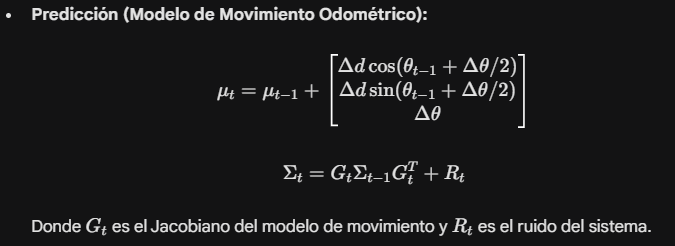 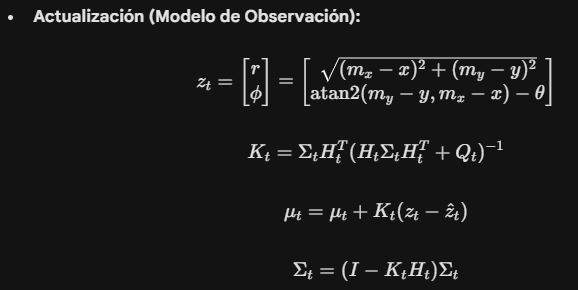

% =========================================================================
% EKF-SLAM para Robot MiR100 usando datos ROS (rosbag)
% =========================================================================
clear; clc; close all;

%% 1. Cargar el archivo ROSBAG
% Reemplaza 'mir100_data.bag' con la ruta real de tu archivo
filePath = 'mir_basics_20251210_114529.bag'; 
bag = rosbag(filePath);

% Seleccionar los tópicos relevantes
bagOdom = select(bag, 'Topic', '/odom');
bagScan = select(bag, 'Topic', '/scan');

% Leer los mensajes (esto puede tomar tiempo dependiendo del tamaño del bag)
disp('Leyendo mensajes del rosbag...');
odomMsgs = readMessages(bagOdom, 'DataFormat', 'struct');
scanMsgs = readMessages(bagScan, 'DataFormat', 'struct');

%% 2. Inicialización de Variables y Matrices EKF
% Vector de estado mu: [x, y, theta, m1x, m1y, m2x, m2y, ...]'
% Al inicio, solo conocemos la pose del robot (0,0,0) y el mapa está vacío.
mu = zeros(3, 1); 

% Matriz de covarianza Sigma
Sigma = zeros(3, 3); 

% Ruido del modelo de movimiento (R) y de medición (Q)
R = diag([0.05, 0.05, 0.02].^2); % Ajustar según la precisión de la odometría del MiR100
Q = diag([0.1, deg2rad(2)].^2);  % Ruido del escáner láser (distancia, ángulo)

% Historial para graficar la trayectoria
trajectory = zeros(length(scanMsgs), 3);
map_landmarks = []; % Para guardar los IDs de los landmarks descubiertos

% Variables para el paso de odometría
last_odom_pos = [odomMsgs{1}.Pose.Pose.Position.X, odomMsgs{1}.Pose.Pose.Position.Y];
quat = odomMsgs{1}.Pose.Pose.Orientation;
last_odom_yaw = quat2yaw([quat.W, quat.X, quat.Y, quat.Z]);

%% 3. Bucle Principal de EKF-SLAM
disp('Iniciando EKF-SLAM...');
figure('Name', 'EKF-SLAM MiR100', 'NumberTitle', 'off');
hold on; grid on; axis equal;
xlabel('X [m]'); ylabel('Y [m]'); title('Estimación de Trayectoria y Mapa (EKF-SLAM)');

% Para simplificar la sincronización, iteramos sobre los mensajes del escáner
% y buscamos la odometría más cercana en el tiempo.
for i = 1:length(scanMsgs)

    % --- A. PREDICCIÓN (Modelo de movimiento con Odometría) ---
    % 1. Obtener la lectura actual de odometría (asumimos sincronización por índice/tiempo para este ejemplo)
    curr_odom = odomMsgs{min(i, length(odomMsgs))}; 
    curr_pos = [curr_odom.Pose.Pose.Position.X, curr_odom.Pose.Pose.Position.Y];
    quat = curr_odom.Pose.Pose.Orientation;
    curr_yaw = quat2yaw([quat.W, quat.X, quat.Y, quat.Z]);

    % 2. Calcular deltas (movimiento relativo)
    delta_trans = norm(curr_pos - last_odom_pos);
    delta_rot = angdiff(last_odom_yaw, curr_yaw);

    % 3. Predicción del Estado (Solo se actualizan las componentes del robot)
    theta = mu(3);
    mu(1) = mu(1) + delta_trans * cos(theta + delta_rot/2);
    mu(2) = mu(2) + delta_trans * sin(theta + delta_rot/2);
    mu(3) = wrapToPi(mu(3) + delta_rot);

    % 4. Jacobiano G_t (Derivada respecto al estado)
    N = length(mu);
    Fx = [eye(3), zeros(3, N-3)]; % Matriz de mapeo para afectar solo al robot

    G_t = eye(N) + Fx' * [0, 0, -delta_trans * sin(theta + delta_rot/2);
                          0, 0,  delta_trans * cos(theta + delta_rot/2);
                          0, 0,  0] * Fx;

    % 5. Actualización de la Covarianza
    Sigma = G_t * Sigma * G_t' + Fx' * R * Fx;

    % Actualizar referencias de odometría
    last_odom_pos = curr_pos;
    last_odom_yaw = curr_yaw;

    % --- B. EXTRACCIÓN DE CARACTERÍSTICAS (Landmarks) ---
    scan = scanMsgs{i};
    % FUNCIÓN CRÍTICA: Debes extraer "puntos de interés" del raw lidar.
    % Aquí llamamos a una función simulada. En la realidad, usarías RANSAC o derivadas.
    [z_ranges, z_angles, z_signatures] = extractLandmarksFromScan(scan);

    % --- C. ACTUALIZACIÓN (Corrección con LiDAR) ---
    for j = 1:length(z_ranges)
        r_meas = z_ranges(j);
        phi_meas = z_angles(j);
        signature = z_signatures(j); % ID único o firma de la característica

        % Asociación de datos (Data Association)
        % Buscamos si la característica ya está en el mapa
        idx = find(map_landmarks == signature);

        if isempty(idx)
            % NUEVO LANDMARK: Añadir al estado y covarianza
            map_landmarks = [map_landmarks; signature];

            % Posición estimada del landmark en coordenadas globales
            m_x = mu(1) + r_meas * cos(mu(3) + phi_meas);
            m_y = mu(2) + r_meas * sin(mu(3) + phi_meas);

            mu = [mu; m_x; m_y];

            % Expandir matriz de covarianza (inicializando con incertidumbre infinita teórica, aquí un valor alto)
            Sigma = blkdiag(Sigma, eye(2)*1000); 
            idx = length(map_landmarks); % Nuevo índice
        end

        % ÍNDICES DEL LANDMARK EN EL VECTOR DE ESTADO
        % x_m = 3 + 2*(idx-1) + 1; y_m = 3 + 2*idx
        lm_idx_x = 3 + 2*(idx-1) + 1;
        lm_idx_y = 3 + 2*idx;

        % Predicción de la medición (z_hat)
        delta_x = mu(lm_idx_x) - mu(1);
        delta_y = mu(lm_idx_y) - mu(2);
        q = delta_x^2 + delta_y^2;

        z_hat = [sqrt(q);
                 wrapToPi(atan2(delta_y, delta_x) - mu(3))];

        % Jacobiano H_t
        N = length(mu);
        Fx_j = zeros(5, N);
        Fx_j(1:3, 1:3) = eye(3);
        Fx_j(4:5, lm_idx_x:lm_idx_y) = eye(2);

        h_matrix = [-delta_x/sqrt(q), -delta_y/sqrt(q), 0, delta_x/sqrt(q), delta_y/sqrt(q);
                     delta_y/q,       -delta_x/q,      -1, -delta_y/q,       delta_x/q];

        H_t = h_matrix * Fx_j;

        % Ganancia de Kalman
        S = H_t * Sigma * H_t' + Q;
        K = Sigma * H_t' / S;

        % Actualizar Estado y Covarianza
        innov = [r_meas - z_hat(1); wrapToPi(phi_meas - z_hat(2))];
        mu = mu + K * innov;
        Sigma = (eye(N) - K * H_t) * Sigma;
    end

    % Guardar trayectoria para visualización
    trajectory(i, :) = mu(1:3)';

    % --- D. VISUALIZACIÓN EN TIEMPO REAL ---
    if mod(i, 20) == 0 % Dibujar cada 20 iteraciones para no ralentizar
        cla;
        % Plot trayectoria
        plot(trajectory(1:i, 1), trajectory(1:i, 2), 'b-', 'LineWidth', 1.5);
        % Plot posición actual robot
        plot(mu(1), mu(2), 'ro', 'MarkerFaceColor', 'r');
        % Plot landmarks
        if length(mu) > 3
            plot(mu(4:2:end), mu(5:2:end), 'k*', 'MarkerSize', 5);
        end
        drawnow;
    end
end
disp('SLAM Finalizado.');

%% ========================================================================
% FUNCIONES AUXILIARES
% =========================================================================

function yaw = quat2yaw(q)

Function 'quat2yaw' has already been declared within this scope.

    % q = [w, x, y, z]
    yaw = atan2(2*(q(1)*q(4) + q(2)*q(3)), 1 - 2*(q(3)^2 + q(4)^2));
end

function diff = angdiff(th1, th2)
    diff = wrapToPi(th2 - th1);
end

function [r, phi, sig] = extractLandmarksFromScan(scanMsg)
    % IMPORTANTE: Esta es una función "placeholder". 
    % El LiDAR raw devuelve un vector de distancias en varios ángulos. 
    % Para un EKF-SLAM real, aquí debes implementar un algoritmo de extracción de 
    % características geométricas (ej. líneas, cilindros, esquinas).

    % Simulación temporal de extracción (Evitando nulos o infinitos):
    ranges = scanMsg.Ranges;
    angles = scanMsg.AngleMin : scanMsg.AngleIncrement : scanMsg.AngleMax;

    % Filtro simple para simular landmarks (ej. puntos donde hay "picos" o cambios bruscos)
    % Solo extraeremos un par de puntos al azar para fines de demostración de la estructura.
    r = []; phi = []; sig = [];

    % Implementa tu lógica geométrica real aquí.
end